# Machine-Learning classification example

Objective: to classify with machine-learning methods the set of features in 

DATASETS/FEATURES/Mammography_masses_mal_ben/ ben_feature.xls and mal_feature.xls 

or DATASETS/FEATURES/Brain_MRI_FS_ABIDE/FS_features_ABIDE_males.csv

We will use binary classifiers, e.g. Support Vector Machine (SVM), to distinguish either malignant (data.Out_mal=1) vs. benign (data.Out_mal=0) mass lesions, or subjects with ASD (data.DX_GROUP=1) from Control subjects (data.DX_GROUP=-1). 

Steps of the analysis:

1) Train and test a binary classifier and evaluate the performance in terms of AUC

2) Implement a cross validation methods: (e.g. k-fold cross validation with k=10)

3) Assign an error to AUC

4) Identify most relevant features in the discrimination problem

5) Try to classify the subjects' provenience site from the ABIDE data (take for example the controls from New York (data.FILE_ID, 'NYU') and those from University of Michigan (UM), or Kennedy Krieger Institute (KKI), or University of California Los Angeles (UCLA)

clear
close all

Read the ABIDE data

filename='../DATASETS/FEATURES/Brain_MRI_FS_ABIDE/FS_features_ABIDE_males_someGlobals.csv';
data=readtable(filename, 'ReadRowNames', true);

and define the features to use and the labels.

Features:

data.Properties.VariableNames{5:end}

ans = 'lh_MeanThickness'

ans = 'rh_MeanThickness'

ans = 'lhCortexVol'

ans = 'rhCortexVol'

ans = 'lhCerebralWhiteMatterVol'

ans = 'rhCerebralWhiteMatterVol'

ans = 'TotalGrayVol'

feature_names=data.Properties.VariableNames(5:end)

feature_names = 1×7 cell array
    {'lh_MeanThickness'}    {'rh_MeanThickness'}    {'lhCortexVol'}    {'rhCortexVol'}    {'lhCerebralWhiteMatterVol'}    {'rhCerebralWhiteMatterVol'}    {'TotalGrayVol'}


features=data(:,5:end);

and the labels

data.Properties.VariableNames{4}

ans = 'DX_GROUP'

labels=data.DX_GROUP;  

Uncomment the lines below to read the mass lesion data, and to define the features and labels for that dataset.

% DB_path='/Users/retico/Desktop/Demo_code/DATASETS/FEATURES/Mammography_masses_mal_ben/'
% fileB='ben_feature.xls';
% fileM='mal_feature.xls';
% data=[readtable(strcat(DB_path,fileB), 'ReadRowNames',true);readtable(strcat(DB_path,fileM),'ReadRowNames',true)];
% 
% % and define features and labels
% % features
% data.Properties.VariableNames{2:19}
% feature_names=data.Properties.VariableNames(2:19)
% features=data(:,2:19);
% % labels
% data.Properties.VariableNames{20}
% labels=data.Out_mal;
% %to run SVM, the class labels should be  [-1 1]
% labels= data.Out_mal-data.Out_ben; % [-1 1] for SVM training

## 1) Training a classifier

`fitcsvm` trains or cross-validates a support vector machine (SVM) model for one-class and two-class (binary) classification on a low-dimensional or moderate-dimensional predictor data set.

To train a linear SVM model for binary classification on a high-dimensional data set, that is, a data set that includes many predictor variables, use [`fitclinear`](https://localhost:31515/static/help/stats/fitclinear.html) instead.

[`Mdl`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6-Mdl) `=` `fitcsvm``(`[`Tbl`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6_sep_shared-Tbl)`,`[`Y`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6-Y)`)` returns an SVM classifier trained using the predictor variables in the table `Tbl` and the class labels in vector `Y`.

[`Mdl`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6-Mdl) `=` `fitcsvm``(``___``,`[`Name,Value`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#namevaluepairarguments)`)` specifies options using one or more name-value pair arguments in addition to the input arguments in previous syntaxes. For example, you can specify the type of cross-validation, the cost for misclassification, and the type of score transformation function.

Examples of [`Name,Value`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#namevaluepairarguments) pairs: 

`'KernelFunction','linear'/'gaussian'/'polynomial' `(linear ithe the defaultfor two class classification)

`'Standardize',true `(The software centers and scales each predictor variable ([`X`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6_sep_shared-X) or [`Tbl`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6_sep_shared-Tbl)) by the corresponding weighted column mean and standard deviation, i.e. z-scores the input variables)

... other [`Name,Value`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#namevaluepairarguments) pairs are listed below.

Train a SVM model with fitcsvm

SVMModel =fitcsvm(features,labels,'Standardize',true);
[data.predicted,score_train]=predict(SVMModel,features);
[labels data.predicted]

ans =      1    -1
     1    -1
     1    -1
     1    -1
     1    -1
     1     1
     1     1
     1    -1
     1    -1
     1    -1


scoreNorm= normalize(score_train(:,2),'range')

scoreNorm =     0.4186
    0.3674
    0.4279
    0.4665
    0.4861
    0.6025
    0.5917
    0.4192
    0.4490
    0.4955


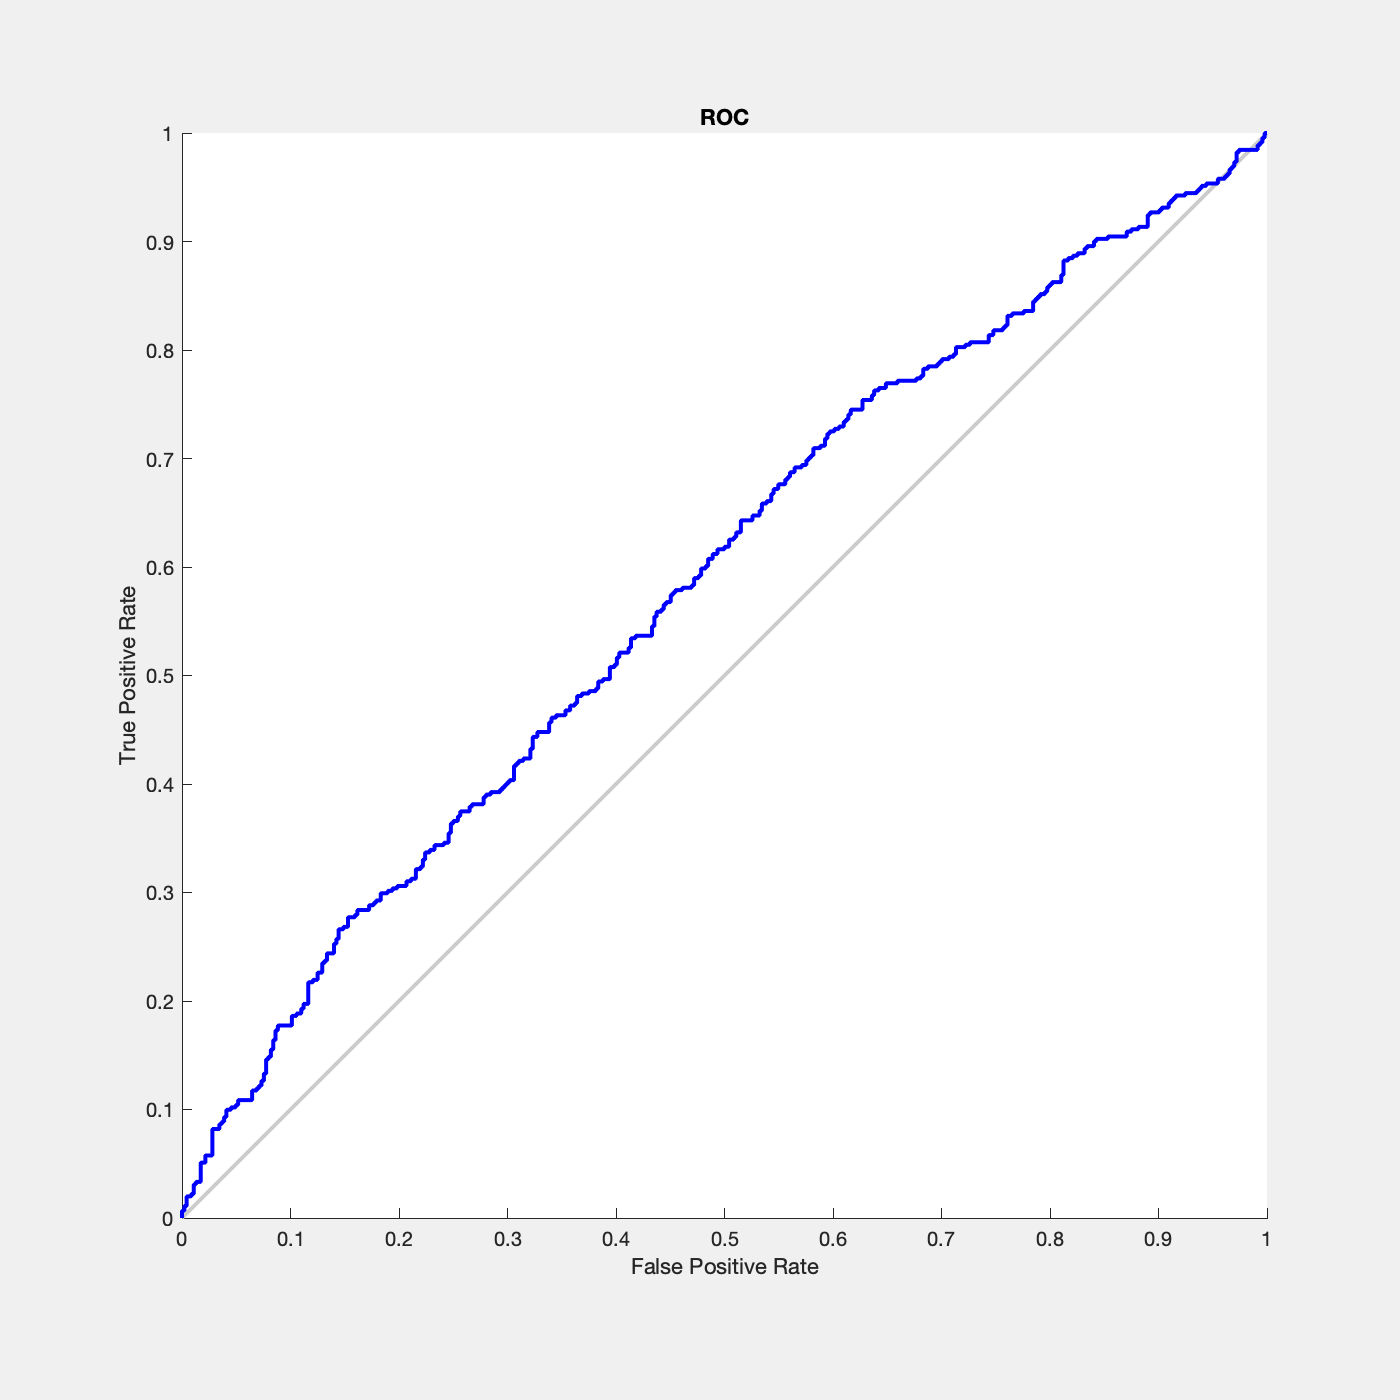

labels_01=(labels+1)/2;
figure;plotroc(labels_01',scoreNorm') % to plot the ROC labels and scorse should be in [0 1]

[X,Y,T,AUC_train]=perfcurve(labels,scoreNorm,1); % labels and scorse should be in [0 1]

We obtain AUC_train = 0.5851 on ABIDE data

and AUC_train = 0.8319 on mammographic masses.

These are the performance obtained on the train data set.

### Splitting the data in the train and test sets

We have to partition data in a train and test set, and provide the performance on the test set. 

part_index=logical(randi([0,1], size(labels))); 
features_train= features(part_index,:);
labels_train= labels(part_index);
features_test= features(~part_index,:);
labels_test=labels(~part_index);

Train the model on train data and compute the performance on both train and test sets

SVMModel =fitcsvm(features_train,labels_train,'Standardize',true);

[class_out_train,score_train] = predict(SVMModel,features_train);
[class_out_test,score_test] = predict(SVMModel,features_test);

Evaluate the performance in yerms of AUC.

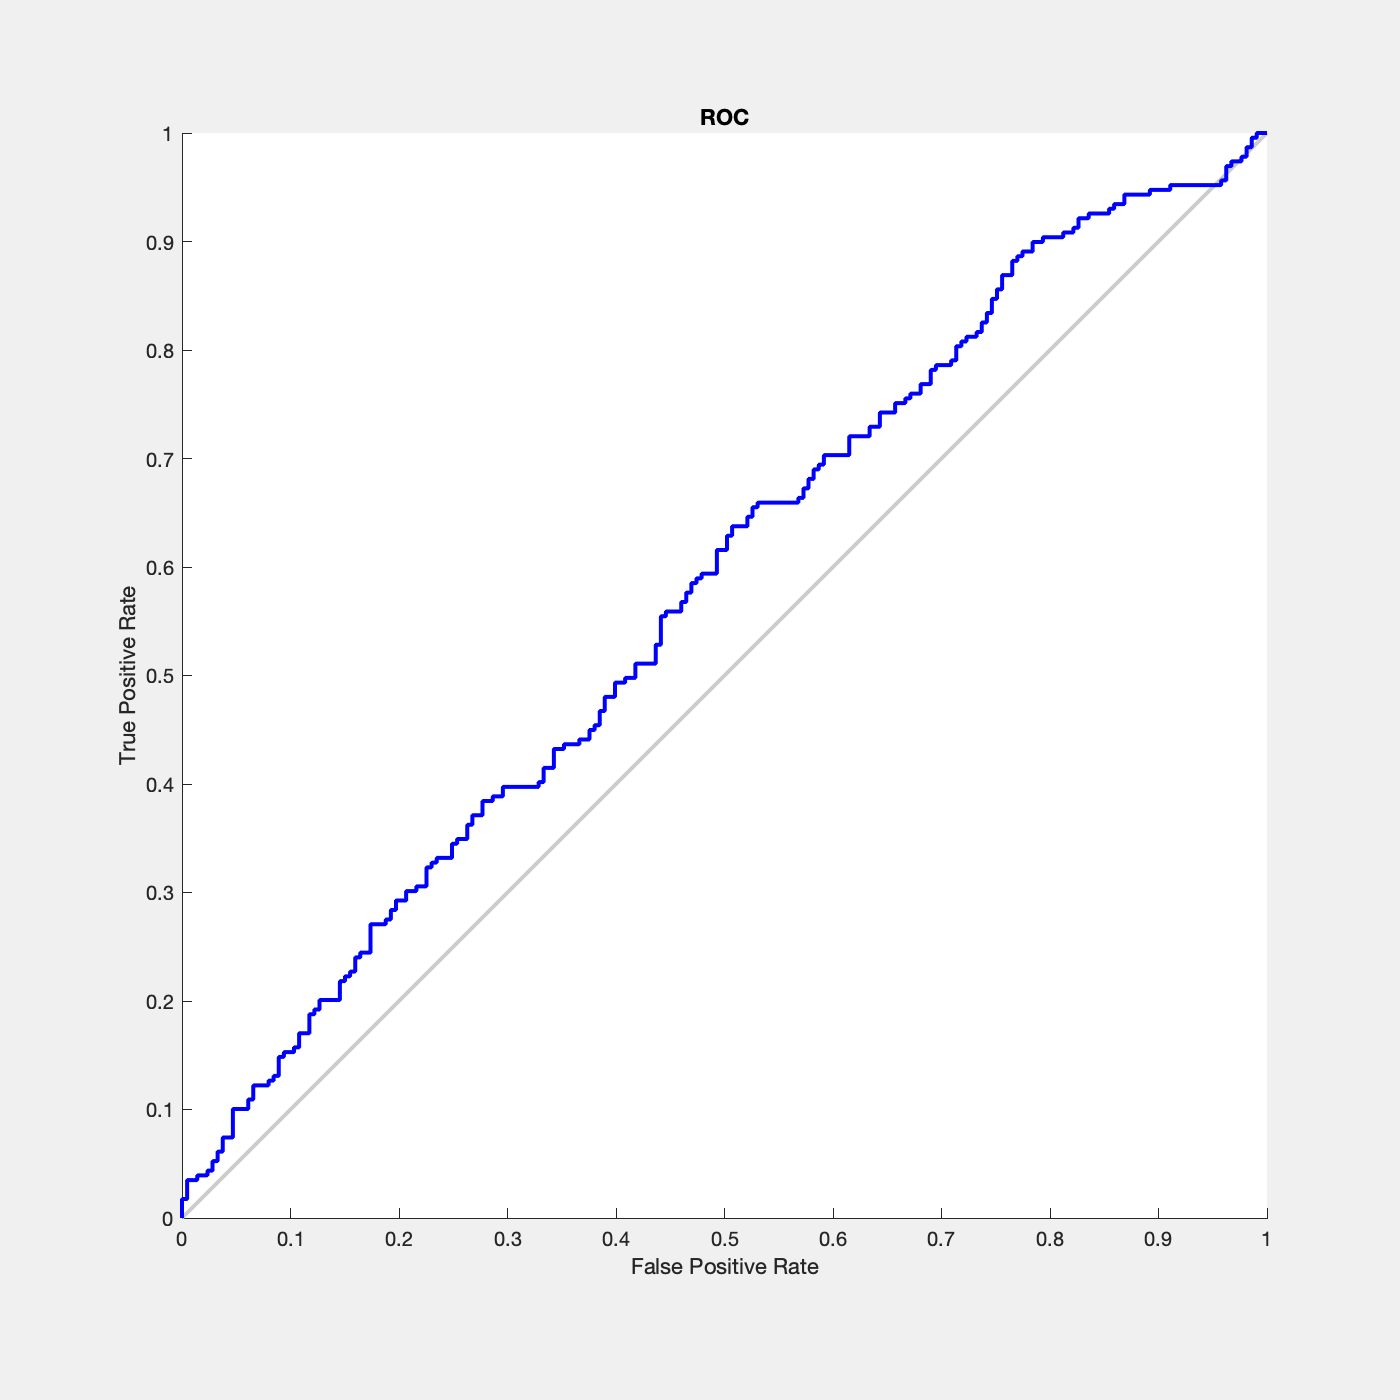

% normalize the scores in the [0 1] range to build the ROC 
score_train_norm=normalize(score_train(:,2),'range'); % consider only the first column
% it is equivalent to
% scoreNorm=(score_train(:,2)-min(score_train(:,2)))/range(score_train(:,2));
score_test_norm=normalize(score_test(:,2),'range'); % consider only the first column
labels_train_01=(labels_train+1)/2;
labels_test_01=(labels_test+1)/2;


[X,Y,T,AUC_train]=perfcurve(labels_train_01,score_train_norm,1);
[X,Y,T,AUC_test]=perfcurve(labels_test_01,score_test_norm,1);

figure;plotroc(labels_train_01',score_train_norm') % devono essere tra [0 1]

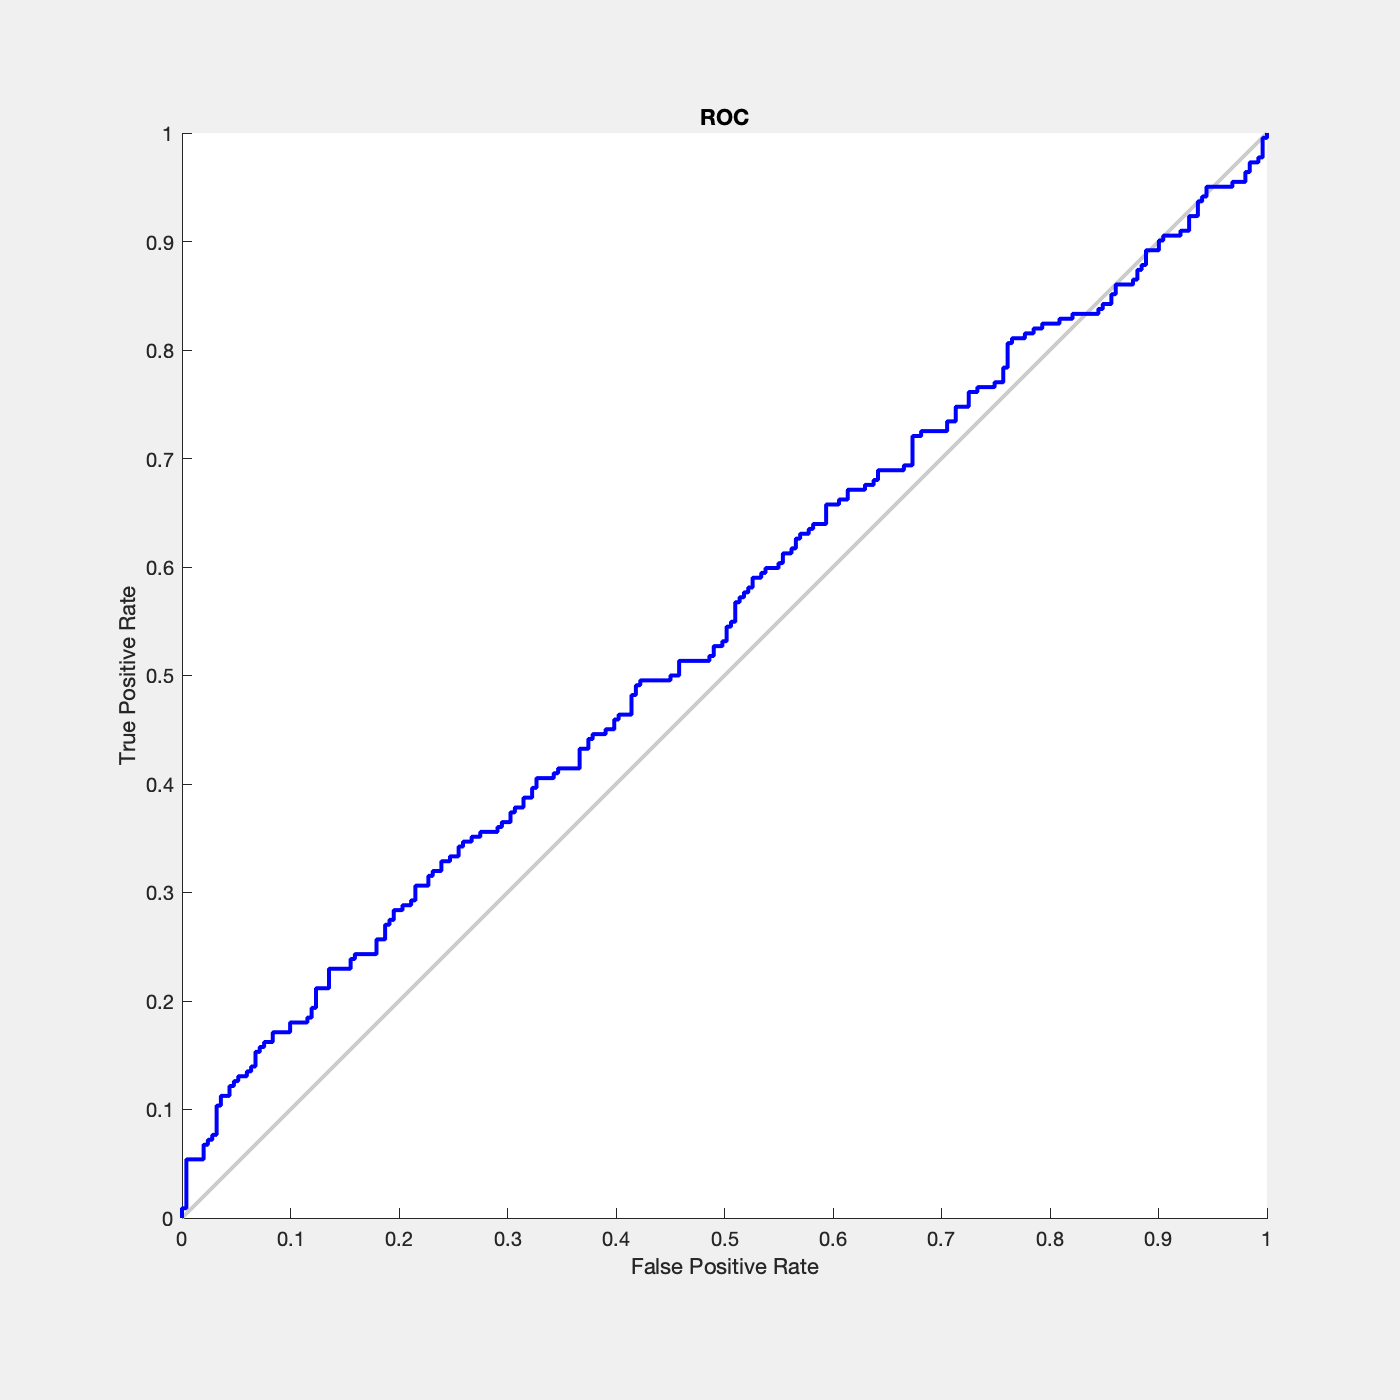

figure;plotroc(labels_test_01',score_test_norm') % devono essere tra [0 1]

The AUC we obtain on the train set is similar to the one we have already obtained (AUC~0,58), the performance on test data is sligthly lower (AUC~0.55).

## 2) Implement a Cross validation (CV)

We can implement different way to partition data into train and test sets, and then implement the code to build a k-fold, hold out, or leave one out CV. 

However, CV is already implemented as an option in `fitcsvm`.   

### k-fold cross validation

[`Mdl`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6-Mdl) `=` `fitcsvm``(`[`Tbl`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6_sep_shared-Tbl)`,`[`Y`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6-Y)`,`[`Name,Value`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#namevaluepairarguments)`)` 

You can specify the type of cross-validation, the cost for misclassification, and the type of score transformation function, through the  [`Name,Value`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#namevaluepairarguments) pairs:

`'Crossval','on' `(the software trains a cross-validated classifier with 10 folds)

You can override this cross-validation setting using the [`CVPartition`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6_sep_shared-CVPartition), [`Holdout`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6_sep_shared-Holdout), [`KFold`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6_sep_shared-KFold), or [`Leaveout`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6_sep_shared-Leaveout) name-value pair argument. 

For [`CVPartition`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6_sep_shared-CVPartition) you first have to create your partition:

`cvp = cvpartition(500,'KFold',5) `

then pass it in the name-value pair

`'CVPartition',cvp. `

For the other methods, you cas use the following name-value pairs:

`'Holdout',0.1 (`Randomly select and reserve `p*100`% of the data as validation data, and train the model using the rest of the data.`)`

`'KFold',5`

`'Leaveout','on'`

Alternatively, cross-validate later by passing [`Mdl`](https://localhost:31515/static/help/stats/fitcsvm.html?searchHighlight=fitcsvm&searchResultIndex=1#bt9w6j6-Mdl) to [`crossval`](https://localhost:31515/static/help/stats/classificationsvm.crossval.html).

We try the default choice, i.e.  `'Crossval','on' `(the software trains a cross-validated classifier with 10 folds):

SVMModelCV =fitcsvm(features,labels,'Standardize',true,'Crossval','on');
%we can see how example are distributed in train and test samples
SVMModelCV.Partition

ans = K-fold cross validation partition
   NumObservations: 915
       NumTestSets: 10
         TrainSize: 824  823  823  823  823  823  824  824  824  824
          TestSize: 91  92  92  92  92  92  91  91  91  91

[class_out_CV, score_CV] =kfoldPredict(SVMModelCV); % Predict response for observations not used for training
scoreNorm= normalize(score_CV(:,2),'range')

scoreNorm =     0.3977
    0.3358
    0.4637
    0.4419
    0.4738
    0.6448
    0.5904
    0.4082
    0.4236
    0.4609


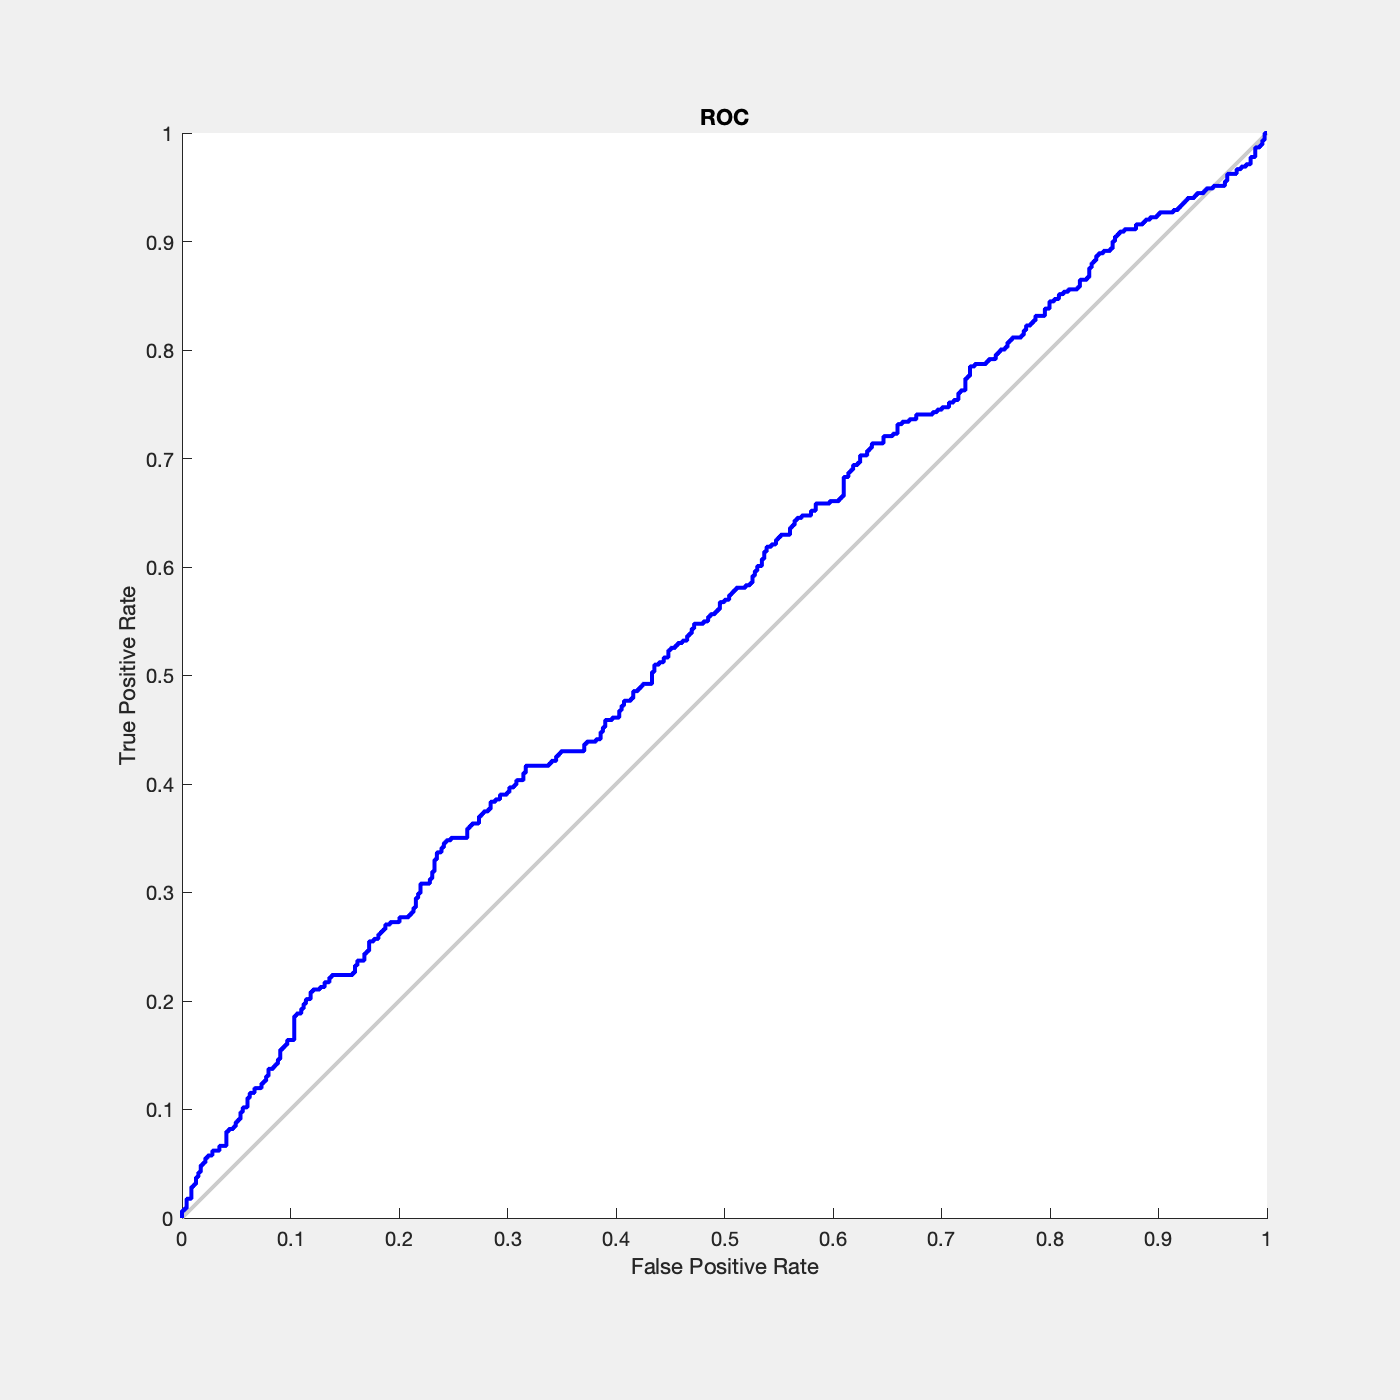

labels_01=(labels+1)/2;
figure;plotroc(labels_01',scoreNorm') 

[X,Y,T,AUC_train]=perfcurve(labels,scoreNorm,1) 

X =          0
         0
         0
         0
    0.0022
    0.0022
    0.0043
    0.0043
    0.0043
    0.0043


Y =          0
    0.0022
    0.0044
    0.0067
    0.0067
    0.0089
    0.0089
    0.0111
    0.0133
    0.0155


T =     1.0000
    1.0000
    0.8614
    0.8219
    0.7837
    0.7753
    0.7691
    0.7630
    0.7526
    0.7491


AUC_train = 0.5573

We obtain AUC-CV~0.55 on ABIDE cohort, and  AUC-CV~0.77 on mammographic masses. 

## 3) How we can assign an error to AUC?

The SVM training with  `'Crossval','on' `can be repeated a number of times (e.g. at least 10 times) to provide an average AUC and to assign it an error (its standard deviation). 

Create a function named `SVMtrainCV` with the code in last code box and call it ten times:

AUC=[]


AUC =

     []



for i=1:10
    AUC=[AUC,SVMtrainCV(features,labels)];
end
results=strcat('The performance of the SVM classifier is AUC= ',num2str(mean(AUC),4),char(177),num2str(std(AUC),2))

results = 'The performance of the SVM classifier is AUC=0.5519±0.0046'

char(177) provides the pus/minus symbol.

## 4) Identify most relevant features in the discrimination problem

When we use linear-kernel SVM, it is strightforward to make a ranking of the feature contribution to class discrimination. The hyperplane weights (SVMModel.Beta) reflect the relative contribution of each feature in the classification problem. 

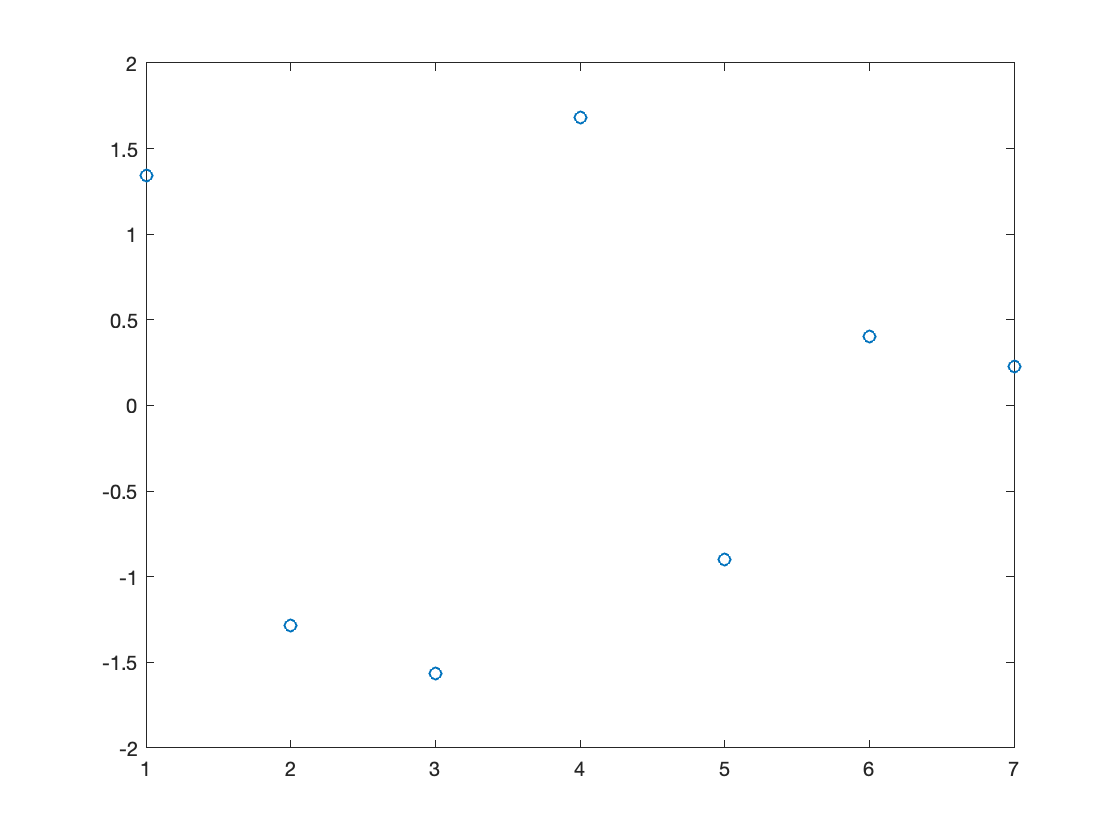

figure; plot(SVMModel.Beta,'o')

I can represent the weight in a `bar` graph, to put the name of the features in the x axis 

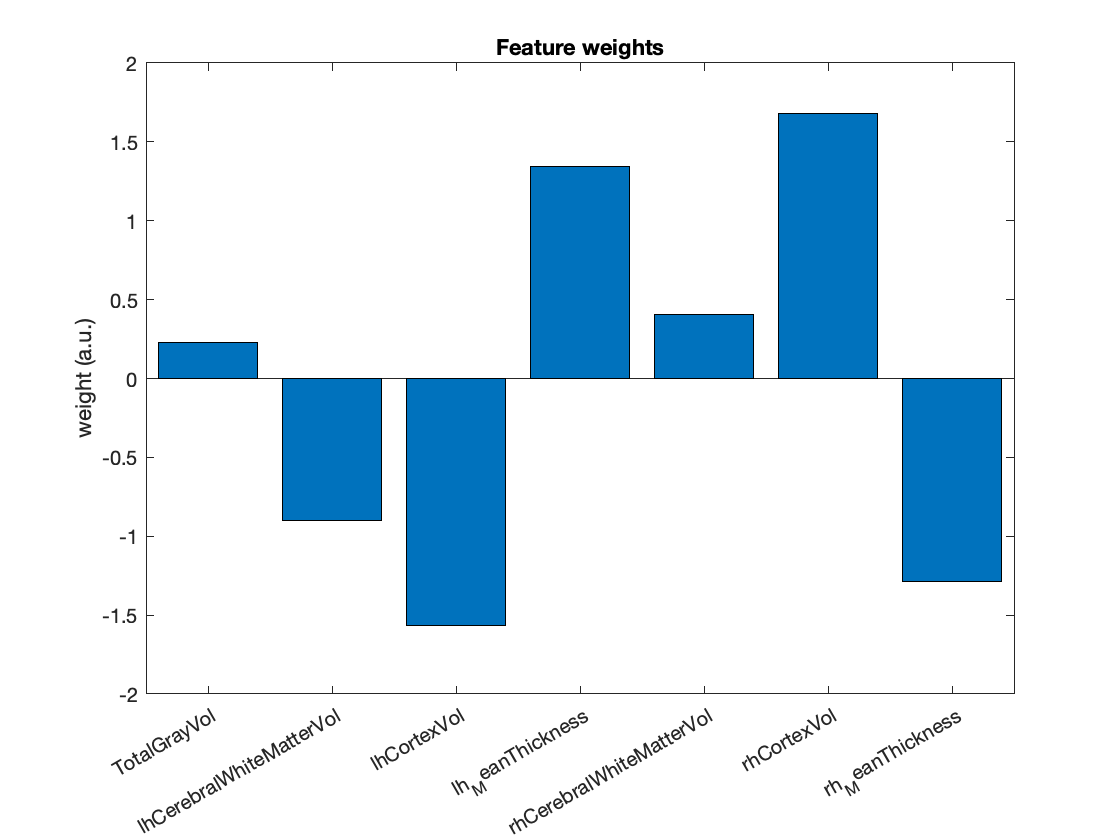

figure; bar(categorical(feature_names),SVMModel.Beta)
angle=30; xtickangle(angle)
ylabel('weight (a.u.)')
title('Feature weights')

We can keep e.g. the most relevant features (e.g. those with abs(beta)>0.5 ) and repeat the classification with this rediced dataset

feature_names_best=feature_names((SVMModel.Beta)>0.5)

feature_names_best = 1×2 cell array
    {'lh_MeanThickness'}    {'rhCortexVol'}


## 5) Try to classify the subjects' provenience site on the ABIDE data 

clear 
close all
filename='../DATASETS/FEATURES/Brain_MRI_FS_ABIDE/FS_features_ABIDE_males.csv';
%filename='../DATASETS/FEATURES/Brain_MRI_FS_ABIDE/FS_features_ABIDE_males_someGlobals.csv';
data=readtable(filename, 'ReadRowNames', true);

Take for example the controls from New York University (data.FILE_ID, 'NYU') and those from University of Michigan (UM), or Kennedy Krieger Institute (KKI), or University of California Los Angeles (UCLA).

Select data

data1=data(contains(data.FILE_ID, 'NYU') & data.DX_GROUP==-1, :);
data2=data(contains(data.FILE_ID, 'KKI') & data.DX_GROUP==-1, :);
%data2=data(contains(data.FILE_ID, 'UM') & data.DX_GROUP==-1, :);
%data2=data(contains(data.FILE_ID, 'UCLA') & data.DX_GROUP==-1, :);

% to check NYU "-1" vs NYU "1" uncomment the following line and 
% do not change the label
%data2=data(contains(data.FILE_ID, 'NYU') & data.DX_GROUP==1, :); 

Change the class label for examples of one of the two sites:

data1.DX_GROUP=-1*data1.DX_GROUP;

Concatenate the dataset

data12=[data1;data2];

Define features and labels.

Features:

data12.Properties.VariableNames{5:end}

ans = 'lh_caudalanteriorcingulate_SurfArea'

ans = 'lh_caudalanteriorcingulate_GrayVol'

ans = 'lh_caudalanteriorcingulate_ThickAvg'

ans = 'lh_caudalanteriorcingulate_ThickStd'

ans = 'lh_caudalanteriorcingulate_MeanCurv'

ans = 'lh_caudalanteriorcingulate_CurvInd'

ans = 'lh_caudalmiddlefrontal_SurfArea'

ans = 'lh_caudalmiddlefrontal_GrayVol'

ans = 'lh_caudalmiddlefrontal_ThickAvg'

ans = 'lh_caudalmiddlefrontal_ThickStd'

ans = 'lh_caudalmiddlefrontal_MeanCurv'

ans = 'lh_caudalmiddlefrontal_CurvInd'

ans = 'lh_cuneus_SurfArea'

ans = 'lh_cuneus_GrayVol'

ans = 'lh_cuneus_ThickAvg'

ans = 'lh_cuneus_ThickStd'

ans = 'lh_cuneus_MeanCurv'

ans = 'lh_cuneus_CurvInd'

ans = 'lh_entorhinal_SurfArea'

ans = 'lh_entorhinal_GrayVol'

ans = 'lh_entorhinal_ThickAvg'

ans = 'lh_entorhinal_ThickStd'

ans = 'lh_entorhinal_MeanCurv'

ans = 'lh_entorhinal_CurvInd'

ans = 'lh_fusiform_SurfArea'

ans = 'lh_fusiform_GrayVol'

ans = 'lh_fusiform_ThickAvg'

ans = 'lh_fusiform_ThickStd'

ans = 'lh_fusiform_MeanCurv'

ans = 'lh_fusiform_CurvInd'

ans = 'lh_inferiorparietal_SurfArea'

ans = 'lh_inferiorparietal_GrayVol'

ans = 'lh_inferiorparietal_ThickAvg'

ans = 'lh_inferiorparietal_ThickStd'

ans = 'lh_inferiorparietal_MeanCurv'

ans = 'lh_inferiorparietal_CurvInd'

ans = 'lh_inferiortemporal_SurfArea'

ans = 'lh_inferiortemporal_GrayVol'

ans = 'lh_inferiortemporal_ThickAvg'

ans = 'lh_inferiortemporal_ThickStd'

ans = 'lh_inferiortemporal_MeanCurv'

ans = 'lh_inferiortemporal_CurvInd'

ans = 'lh_isthmuscingulate_SurfArea'

ans = 'lh_isthmuscingulate_GrayVol'

ans = 'lh_isthmuscingulate_ThickAvg'

ans = 'lh_isthmuscingulate_ThickStd'

ans = 'lh_isthmuscingulate_MeanCurv'

ans = 'lh_isthmuscingulate_CurvInd'

ans = 'lh_lateraloccipital_SurfArea'

ans = 'lh_lateraloccipital_GrayVol'

ans = 'lh_lateraloccipital_ThickAvg'

ans = 'lh_lateraloccipital_ThickStd'

ans = 'lh_lateraloccipital_MeanCurv'

ans = 'lh_lateraloccipital_CurvInd'

ans = 'lh_lateralorbitofrontal_SurfArea'

ans = 'lh_lateralorbitofrontal_GrayVol'

ans = 'lh_lateralorbitofrontal_ThickAvg'

ans = 'lh_lateralorbitofrontal_ThickStd'

ans = 'lh_lateralorbitofrontal_MeanCurv'

ans = 'lh_lateralorbitofrontal_CurvInd'

ans = 'lh_lingual_SurfArea'

ans = 'lh_lingual_GrayVol'

ans = 'lh_lingual_ThickAvg'

ans = 'lh_lingual_ThickStd'

ans = 'lh_lingual_MeanCurv'

ans = 'lh_lingual_CurvInd'

ans = 'lh_medialorbitofrontal_SurfArea'

ans = 'lh_medialorbitofrontal_GrayVol'

ans = 'lh_medialorbitofrontal_ThickAvg'

ans = 'lh_medialorbitofrontal_ThickStd'

ans = 'lh_medialorbitofrontal_MeanCurv'

ans = 'lh_medialorbitofrontal_CurvInd'

ans = 'lh_middletemporal_SurfArea'

ans = 'lh_middletemporal_GrayVol'

ans = 'lh_middletemporal_ThickAvg'

ans = 'lh_middletemporal_ThickStd'

ans = 'lh_middletemporal_MeanCurv'

ans = 'lh_middletemporal_CurvInd'

ans = 'lh_parahippocampal_SurfArea'

ans = 'lh_parahippocampal_GrayVol'

ans = 'lh_parahippocampal_ThickAvg'

ans = 'lh_parahippocampal_ThickStd'

ans = 'lh_parahippocampal_MeanCurv'

ans = 'lh_parahippocampal_CurvInd'

ans = 'lh_paracentral_SurfArea'

ans = 'lh_paracentral_GrayVol'

ans = 'lh_paracentral_ThickAvg'

ans = 'lh_paracentral_ThickStd'

ans = 'lh_paracentral_MeanCurv'

ans = 'lh_paracentral_CurvInd'

ans = 'lh_parsopercularis_SurfArea'

ans = 'lh_parsopercularis_GrayVol'

ans = 'lh_parsopercularis_ThickAvg'

ans = 'lh_parsopercularis_ThickStd'

ans = 'lh_parsopercularis_MeanCurv'

ans = 'lh_parsopercularis_CurvInd'

ans = 'lh_parsorbitalis_SurfArea'

ans = 'lh_parsorbitalis_GrayVol'

ans = 'lh_parsorbitalis_ThickAvg'

ans = 'lh_parsorbitalis_ThickStd'

ans = 'lh_parsorbitalis_MeanCurv'

ans = 'lh_parsorbitalis_CurvInd'

ans = 'lh_parstriangularis_SurfArea'

ans = 'lh_parstriangularis_GrayVol'

ans = 'lh_parstriangularis_ThickAvg'

ans = 'lh_parstriangularis_ThickStd'

ans = 'lh_parstriangularis_MeanCurv'

ans = 'lh_parstriangularis_CurvInd'

ans = 'lh_pericalcarine_SurfArea'

ans = 'lh_pericalcarine_GrayVol'

ans = 'lh_pericalcarine_ThickAvg'

ans = 'lh_pericalcarine_ThickStd'

ans = 'lh_pericalcarine_MeanCurv'

ans = 'lh_pericalcarine_CurvInd'

ans = 'lh_postcentral_SurfArea'

ans = 'lh_postcentral_GrayVol'

ans = 'lh_postcentral_ThickAvg'

ans = 'lh_postcentral_ThickStd'

ans = 'lh_postcentral_MeanCurv'

ans = 'lh_postcentral_CurvInd'

ans = 'lh_posteriorcingulate_SurfArea'

ans = 'lh_posteriorcingulate_GrayVol'

ans = 'lh_posteriorcingulate_ThickAvg'

ans = 'lh_posteriorcingulate_ThickStd'

ans = 'lh_posteriorcingulate_MeanCurv'

ans = 'lh_posteriorcingulate_CurvInd'

ans = 'lh_precentral_SurfArea'

ans = 'lh_precentral_GrayVol'

ans = 'lh_precentral_ThickAvg'

ans = 'lh_precentral_ThickStd'

ans = 'lh_precentral_MeanCurv'

ans = 'lh_precentral_CurvInd'

ans = 'lh_precuneus_SurfArea'

ans = 'lh_precuneus_GrayVol'

ans = 'lh_precuneus_ThickAvg'

ans = 'lh_precuneus_ThickStd'

ans = 'lh_precuneus_MeanCurv'

ans = 'lh_precuneus_CurvInd'

ans = 'lh_rostralanteriorcingulate_SurfArea'

ans = 'lh_rostralanteriorcingulate_GrayVol'

ans = 'lh_rostralanteriorcingulate_ThickAvg'

ans = 'lh_rostralanteriorcingulate_ThickStd'

ans = 'lh_rostralanteriorcingulate_MeanCurv'

ans = 'lh_rostralanteriorcingulate_CurvInd'

ans = 'lh_rostralmiddlefrontal_SurfArea'

ans = 'lh_rostralmiddlefrontal_GrayVol'

ans = 'lh_rostralmiddlefrontal_ThickAvg'

ans = 'lh_rostralmiddlefrontal_ThickStd'

ans = 'lh_rostralmiddlefrontal_MeanCurv'

ans = 'lh_rostralmiddlefrontal_CurvInd'

ans = 'lh_superiorfrontal_SurfArea'

ans = 'lh_superiorfrontal_GrayVol'

ans = 'lh_superiorfrontal_ThickAvg'

ans = 'lh_superiorfrontal_ThickStd'

ans = 'lh_superiorfrontal_MeanCurv'

ans = 'lh_superiorfrontal_CurvInd'

ans = 'lh_superiorparietal_SurfArea'

ans = 'lh_superiorparietal_GrayVol'

ans = 'lh_superiorparietal_ThickAvg'

ans = 'lh_superiorparietal_ThickStd'

ans = 'lh_superiorparietal_MeanCurv'

ans = 'lh_superiorparietal_CurvInd'

ans = 'lh_superiortemporal_SurfArea'

ans = 'lh_superiortemporal_GrayVol'

ans = 'lh_superiortemporal_ThickAvg'

ans = 'lh_superiortemporal_ThickStd'

ans = 'lh_superiortemporal_MeanCurv'

ans = 'lh_superiortemporal_CurvInd'

ans = 'lh_supramarginal_SurfArea'

ans = 'lh_supramarginal_GrayVol'

ans = 'lh_supramarginal_ThickAvg'

ans = 'lh_supramarginal_ThickStd'

ans = 'lh_supramarginal_MeanCurv'

ans = 'lh_supramarginal_CurvInd'

ans = 'lh_transversetemporal_SurfArea'

ans = 'lh_transversetemporal_GrayVol'

ans = 'lh_transversetemporal_ThickAvg'

ans = 'lh_transversetemporal_ThickStd'

ans = 'lh_transversetemporal_MeanCurv'

ans = 'lh_transversetemporal_CurvInd'

ans = 'lh_insula_SurfArea'

ans = 'lh_insula_GrayVol'

ans = 'lh_insula_ThickAvg'

ans = 'lh_insula_ThickStd'

ans = 'lh_insula_MeanCurv'

ans = 'lh_insula_CurvInd'

ans = 'rh_caudalanteriorcingulate_SurfArea'

ans = 'rh_caudalanteriorcingulate_GrayVol'

ans = 'rh_caudalanteriorcingulate_ThickAvg'

ans = 'rh_caudalanteriorcingulate_ThickStd'

ans = 'rh_caudalanteriorcingulate_MeanCurv'

ans = 'rh_caudalanteriorcingulate_CurvInd'

ans = 'rh_caudalmiddlefrontal_SurfArea'

ans = 'rh_caudalmiddlefrontal_GrayVol'

ans = 'rh_caudalmiddlefrontal_ThickAvg'

ans = 'rh_caudalmiddlefrontal_ThickStd'

ans = 'rh_caudalmiddlefrontal_MeanCurv'

ans = 'rh_caudalmiddlefrontal_CurvInd'

ans = 'rh_cuneus_SurfArea'

ans = 'rh_cuneus_GrayVol'

ans = 'rh_cuneus_ThickAvg'

ans = 'rh_cuneus_ThickStd'

ans = 'rh_cuneus_MeanCurv'

ans = 'rh_cuneus_CurvInd'

ans = 'rh_entorhinal_SurfArea'

ans = 'rh_entorhinal_GrayVol'

ans = 'rh_entorhinal_ThickAvg'

ans = 'rh_entorhinal_ThickStd'

ans = 'rh_entorhinal_MeanCurv'

ans = 'rh_entorhinal_CurvInd'

ans = 'rh_fusiform_SurfArea'

ans = 'rh_fusiform_GrayVol'

ans = 'rh_fusiform_ThickAvg'

ans = 'rh_fusiform_ThickStd'

ans = 'rh_fusiform_MeanCurv'

ans = 'rh_fusiform_CurvInd'

ans = 'rh_inferiorparietal_SurfArea'

ans = 'rh_inferiorparietal_GrayVol'

ans = 'rh_inferiorparietal_ThickAvg'

ans = 'rh_inferiorparietal_ThickStd'

ans = 'rh_inferiorparietal_MeanCurv'

ans = 'rh_inferiorparietal_CurvInd'

ans = 'rh_inferiortemporal_SurfArea'

ans = 'rh_inferiortemporal_GrayVol'

ans = 'rh_inferiortemporal_ThickAvg'

ans = 'rh_inferiortemporal_ThickStd'

ans = 'rh_inferiortemporal_MeanCurv'

ans = 'rh_inferiortemporal_CurvInd'

ans = 'rh_isthmuscingulate_SurfArea'

ans = 'rh_isthmuscingulate_GrayVol'

ans = 'rh_isthmuscingulate_ThickAvg'

ans = 'rh_isthmuscingulate_ThickStd'

ans = 'rh_isthmuscingulate_MeanCurv'

ans = 'rh_isthmuscingulate_CurvInd'

ans = 'rh_lateraloccipital_SurfArea'

ans = 'rh_lateraloccipital_GrayVol'

ans = 'rh_lateraloccipital_ThickAvg'

ans = 'rh_lateraloccipital_ThickStd'

ans = 'rh_lateraloccipital_MeanCurv'

ans = 'rh_lateraloccipital_CurvInd'

ans = 'rh_lateralorbitofrontal_SurfArea'

ans = 'rh_lateralorbitofrontal_GrayVol'

ans = 'rh_lateralorbitofrontal_ThickAvg'

ans = 'rh_lateralorbitofrontal_ThickStd'

ans = 'rh_lateralorbitofrontal_MeanCurv'

ans = 'rh_lateralorbitofrontal_CurvInd'

ans = 'rh_lingual_SurfArea'

ans = 'rh_lingual_GrayVol'

ans = 'rh_lingual_ThickAvg'

ans = 'rh_lingual_ThickStd'

ans = 'rh_lingual_MeanCurv'

ans = 'rh_lingual_CurvInd'

ans = 'rh_medialorbitofrontal_SurfArea'

ans = 'rh_medialorbitofrontal_GrayVol'

ans = 'rh_medialorbitofrontal_ThickAvg'

ans = 'rh_medialorbitofrontal_ThickStd'

ans = 'rh_medialorbitofrontal_MeanCurv'

ans = 'rh_medialorbitofrontal_CurvInd'

ans = 'rh_middletemporal_SurfArea'

ans = 'rh_middletemporal_GrayVol'

ans = 'rh_middletemporal_ThickAvg'

ans = 'rh_middletemporal_ThickStd'

ans = 'rh_middletemporal_MeanCurv'

ans = 'rh_middletemporal_CurvInd'

ans = 'rh_parahippocampal_SurfArea'

ans = 'rh_parahippocampal_GrayVol'

ans = 'rh_parahippocampal_ThickAvg'

ans = 'rh_parahippocampal_ThickStd'

ans = 'rh_parahippocampal_MeanCurv'

ans = 'rh_parahippocampal_CurvInd'

ans = 'rh_paracentral_SurfArea'

ans = 'rh_paracentral_GrayVol'

ans = 'rh_paracentral_ThickAvg'

ans = 'rh_paracentral_ThickStd'

ans = 'rh_paracentral_MeanCurv'

ans = 'rh_paracentral_CurvInd'

ans = 'rh_parsopercularis_SurfArea'

ans = 'rh_parsopercularis_GrayVol'

ans = 'rh_parsopercularis_ThickAvg'

ans = 'rh_parsopercularis_ThickStd'

ans = 'rh_parsopercularis_MeanCurv'

ans = 'rh_parsopercularis_CurvInd'

ans = 'rh_parsorbitalis_SurfArea'

ans = 'rh_parsorbitalis_GrayVol'

ans = 'rh_parsorbitalis_ThickAvg'

ans = 'rh_parsorbitalis_ThickStd'

ans = 'rh_parsorbitalis_MeanCurv'

ans = 'rh_parsorbitalis_CurvInd'

ans = 'rh_parstriangularis_SurfArea'

ans = 'rh_parstriangularis_GrayVol'

ans = 'rh_parstriangularis_ThickAvg'

ans = 'rh_parstriangularis_ThickStd'

ans = 'rh_parstriangularis_MeanCurv'

ans = 'rh_parstriangularis_CurvInd'

ans = 'rh_pericalcarine_SurfArea'

ans = 'rh_pericalcarine_GrayVol'

ans = 'rh_pericalcarine_ThickAvg'

ans = 'rh_pericalcarine_ThickStd'

ans = 'rh_pericalcarine_MeanCurv'

ans = 'rh_pericalcarine_CurvInd'

ans = 'rh_postcentral_SurfArea'

ans = 'rh_postcentral_GrayVol'

ans = 'rh_postcentral_ThickAvg'

ans = 'rh_postcentral_ThickStd'

ans = 'rh_postcentral_MeanCurv'

ans = 'rh_postcentral_CurvInd'

ans = 'rh_posteriorcingulate_SurfArea'

ans = 'rh_posteriorcingulate_GrayVol'

ans = 'rh_posteriorcingulate_ThickAvg'

ans = 'rh_posteriorcingulate_ThickStd'

ans = 'rh_posteriorcingulate_MeanCurv'

ans = 'rh_posteriorcingulate_CurvInd'

ans = 'rh_precentral_SurfArea'

ans = 'rh_precentral_GrayVol'

ans = 'rh_precentral_ThickAvg'

ans = 'rh_precentral_ThickStd'

ans = 'rh_precentral_MeanCurv'

ans = 'rh_precentral_CurvInd'

ans = 'rh_precuneus_SurfArea'

ans = 'rh_precuneus_GrayVol'

ans = 'rh_precuneus_ThickAvg'

ans = 'rh_precuneus_ThickStd'

ans = 'rh_precuneus_MeanCurv'

ans = 'rh_precuneus_CurvInd'

ans = 'rh_rostralanteriorcingulate_SurfArea'

ans = 'rh_rostralanteriorcingulate_GrayVol'

ans = 'rh_rostralanteriorcingulate_ThickAvg'

ans = 'rh_rostralanteriorcingulate_ThickStd'

ans = 'rh_rostralanteriorcingulate_MeanCurv'

ans = 'rh_rostralanteriorcingulate_CurvInd'

ans = 'rh_rostralmiddlefrontal_SurfArea'

ans = 'rh_rostralmiddlefrontal_GrayVol'

ans = 'rh_rostralmiddlefrontal_ThickAvg'

ans = 'rh_rostralmiddlefrontal_ThickStd'

ans = 'rh_rostralmiddlefrontal_MeanCurv'

ans = 'rh_rostralmiddlefrontal_CurvInd'

ans = 'rh_superiorfrontal_SurfArea'

ans = 'rh_superiorfrontal_GrayVol'

ans = 'rh_superiorfrontal_ThickAvg'

ans = 'rh_superiorfrontal_ThickStd'

ans = 'rh_superiorfrontal_MeanCurv'

ans = 'rh_superiorfrontal_CurvInd'

ans = 'rh_superiorparietal_SurfArea'

ans = 'rh_superiorparietal_GrayVol'

ans = 'rh_superiorparietal_ThickAvg'

ans = 'rh_superiorparietal_ThickStd'

ans = 'rh_superiorparietal_MeanCurv'

ans = 'rh_superiorparietal_CurvInd'

ans = 'rh_superiortemporal_SurfArea'

ans = 'rh_superiortemporal_GrayVol'

ans = 'rh_superiortemporal_ThickAvg'

ans = 'rh_superiortemporal_ThickStd'

ans = 'rh_superiortemporal_MeanCurv'

ans = 'rh_superiortemporal_CurvInd'

ans = 'rh_supramarginal_SurfArea'

ans = 'rh_supramarginal_GrayVol'

ans = 'rh_supramarginal_ThickAvg'

ans = 'rh_supramarginal_ThickStd'

ans = 'rh_supramarginal_MeanCurv'

ans = 'rh_supramarginal_CurvInd'

ans = 'rh_transversetemporal_SurfArea'

ans = 'rh_transversetemporal_GrayVol'

ans = 'rh_transversetemporal_ThickAvg'

ans = 'rh_transversetemporal_ThickStd'

ans = 'rh_transversetemporal_MeanCurv'

ans = 'rh_transversetemporal_CurvInd'

ans = 'rh_insula_SurfArea'

ans = 'rh_insula_GrayVol'

ans = 'rh_insula_ThickAvg'

ans = 'rh_insula_ThickStd'

ans = 'rh_insula_MeanCurv'

ans = 'rh_insula_CurvInd'

ans = 'Left_Lateral_Ventricle_Volume_mm3'

ans = 'Left_Inf_Lat_Vent_Volume_mm3'

ans = 'Left_Cerebellum_White_Matter_Volume_mm3'

ans = 'Left_Cerebellum_Cortex_Volume_mm3'

ans = 'Left_Thalamus_Proper_Volume_mm3'

ans = 'Left_Caudate_Volume_mm3'

ans = 'Left_Putamen_Volume_mm3'

ans = 'Left_Pallidum_Volume_mm3'

ans = 'x3rd_Ventricle_Volume_mm3'

ans = 'x4th_Ventricle_Volume_mm3'

ans = 'Brain_Stem_Volume_mm3'

ans = 'Left_Hippocampus_Volume_mm3'

ans = 'Left_Amygdala_Volume_mm3'

ans = 'CSF_Volume_mm3'

ans = 'Left_Accumbens_area_Volume_mm3'

ans = 'Left_VentralDC_Volume_mm3'

ans = 'Left_vessel_Volume_mm3'

ans = 'Left_choroid_plexus_Volume_mm3'

ans = 'Right_Lateral_Ventricle_Volume_mm3'

ans = 'Right_Inf_Lat_Vent_Volume_mm3'

ans = 'Right_Cerebellum_White_Matter_Volume_mm3'

ans = 'Right_Cerebellum_Cortex_Volume_mm3'

ans = 'Right_Thalamus_Proper_Volume_mm3'

ans = 'Right_Caudate_Volume_mm3'

ans = 'Right_Putamen_Volume_mm3'

ans = 'Right_Pallidum_Volume_mm3'

ans = 'Right_Hippocampus_Volume_mm3'

ans = 'Right_Amygdala_Volume_mm3'

ans = 'Right_Accumbens_area_Volume_mm3'

ans = 'Right_VentralDC_Volume_mm3'

ans = 'Right_vessel_Volume_mm3'

ans = 'Right_choroid_plexus_Volume_mm3'

ans = 'x5th_Ventricle_Volume_mm3'

ans = 'Optic_Chiasm_Volume_mm3'

ans = 'CC_Posterior_Volume_mm3'

ans = 'CC_Mid_Posterior_Volume_mm3'

ans = 'CC_Central_Volume_mm3'

ans = 'CC_Mid_Anterior_Volume_mm3'

ans = 'CC_Anterior_Volume_mm3'

ans = 'lh_MeanThickness'

ans = 'rh_MeanThickness'

ans = 'VentricleChoroidVol'

ans = 'lhCortexVol'

ans = 'rhCortexVol'

ans = 'lhCerebralWhiteMatterVol'

ans = 'rhCerebralWhiteMatterVol'

ans = 'TotalGrayVol'

feature_names=data12.Properties.VariableNames(5:end)

feature_names = 1×419 cell array
  Columns 1 through 400

    {'lh_caudalanteri…'}    {'lh_caudalanteri…'}    {'lh_caudalanteri…'}    {'lh_caudalanteri…'}    {'lh_caudalanteri…'}    {'lh_caudalanteri…'}    {'lh_caudalmiddle…'}    {'lh_caudalmiddle…'}    {'lh_caudalmiddle…'}    {'lh_caudalmiddle…'}    {'lh_caudalmiddle…'}    {'lh_caudalmiddle…'}    {'lh_cuneus_SurfA…'}    {'lh_cuneus_GrayVol'}    {'lh_cuneus_Thick…'}    {'lh_cuneus_Thick…'}    {'lh_cuneus_MeanC…'}    {'lh_cuneus_CurvInd'}    {'lh_entorhinal_S…'}    {'lh_entorhinal_G…'}    {'lh_entorhinal_T…'}    {'lh_entorhinal_T…'}    {'lh_entorhinal_M…'}    {'lh_entorhinal_C…'}    {'lh_fusiform_Sur…'}    {'lh_fusiform_Gra…'}    {'lh_fusiform_Thi…'}    {'lh_fusiform_Thi…'}    {'lh_fusiform_Mea…'}    {'lh_fusiform_Cur…'}    {'lh_inferiorpari…'}    {'lh_inferiorpari…'}    {'lh_inferiorpari…'}    {'lh_inferiorpari…'}    {'lh_inferiorpari…'}    {'lh_inferiorpari…'}    {'lh_inferiortemp…'}    {'lh_inferiortemp…'}    {'lh_inferiortemp…'}    

features=data12(:,5:end);  

Labels:

data12.Properties.VariableNames{4}

ans = 'DX_GROUP'

labels=data12.DX_GROUP; 

AUC=[]


AUC =

     []



for i=1:10
    AUC=[AUC,SVMtrainCV(features,labels)];
end
results=strcat('The performance of the SVM classifier is AUC= ',num2str(mean(AUC),4),char(177),num2str(std(AUC),2))

results = 'The performance of the SVM classifier is AUC=0.9973±0.0052'

We obtain: 

AUC= 0.863±0.008 in discriminating NYU from KKI data

AUC=0.6192±0.019 in discriminating NYU from UM data

AUC=0.7266±0.014 in discriminating NYU from UCLA data